# Project 1

## Theoretical Validation

clear; clc;

### General Cases

e = [0;0;0];
I = [3 0 0; 0 2 0; 0 0 1];
b3_hat = [0;0;1];

#### Null Case

w_0 = [0;0;0];
w_0_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;0;0];

out_null = runModel(I, g, w_0, e, b3_hat);

e_null = out_null.angle_out(end,:)

e_null =      0     0     0


w_null = out_null.omega(end,:)

w_null =      0     0     0


w_inertial_null = out_null.omega_inertial(end,:)

w_inertial_null =      0     0     0


h_null = out_null.ang_mom(end,:)

h_null =      0     0     0


h_inertial_null = out_null.ang_mom_inertial(end,:)

h_inertial_null =      0     0     0


#### Constant Rotation Case 1

w_0 = [1;0;0];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;0;0];

out_constant1 = runModel(I, g, w_0, e, b3_hat);

e_constant1 = out_constant1.angle_out(out_constant1.tout == 2, :)

e_constant1 =          0    2.0000         0


w_constant1 = out_constant1.omega(out_constant1.tout == 2, :)

w_constant1 =      1     0     0


w_inertial_constant1 = out_constant1.omega_inertial(out_constant1.tout == 2, :)

w_inertial_constant1 =      1     0     0


h_constant1 = out_constant1.ang_mom(out_constant1.tout == 2, :)

h_constant1 =      3     0     0


h_inertial_constant1 = out_constant1.ang_mom_inertial(out_constant1.tout == 2, :)

h_inertial_constant1 =      3     0     0


#### Constant Rotation Case 2

w_0 = [0;1;0];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;0;0];

out_constant2 = runModel(I, g, w_0, e, b3_hat);

e_constant2 = out_constant2.angle_out(out_constant2.tout == 2, :)

e_constant2 =     1.5708    2.0000   -1.5708


w_constant2 = out_constant2.omega(out_constant2.tout == 2, :)

w_constant2 =      0     1     0


w_inertial_constant2 = out_constant2.omega_inertial(out_constant2.tout == 2, :)

w_inertial_constant2 =      0     1     0


h_constant2 = out_constant2.ang_mom(out_constant2.tout == 2, :)

h_constant2 =      0     2     0


h_inertial_constant2 = out_constant2.ang_mom_inertial(out_constant2.tout == 2, :)

h_inertial_constant2 =      0     2     0


#### Constant Rotation Case 3

w_0 = [0;0;1];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;0;0];

out_constant3 = runModel(I, g, w_0, e, b3_hat);


e_constant3 = out_constant3.angle_out(out_constant3.tout == 2, :)

e_constant3 =     2.0000         0         0


w_constant3 = out_constant3.omega(out_constant3.tout == 2, :)

w_constant3 =      0     0     1


w_inertial_constant3 = out_constant3.omega_inertial(out_constant3.tout == 2, :)

w_inertial_constant3 =      0     0     1


h_constant3 = out_constant3.ang_mom(out_constant3.tout == 2, :)

h_constant3 =      0     0     1


h_inertial_constant3 = out_constant3.ang_mom_inertial(out_constant3.tout == 2, :)

h_inertial_constant3 =      0     0     1


#### Constant Torque Case 1

w_0 = [0;0;0];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [1;0;0];

out_torque1 = runModel(I, g, w_0, e, b3_hat);

e_torque1 = out_torque1.angle_out(out_torque1.tout == 3, :)

e_torque1 =          0    1.5000         0


w_torque1 = out_torque1.omega(out_torque1.tout == 3, :)

w_torque1 =     1.0000         0         0


w_inertial_torque1 = out_torque1.omega_inertial(out_torque1.tout == 3, :)

w_inertial_torque1 =     1.0000         0         0


h_torque1 = out_torque1.ang_mom(out_torque1.tout == 3, :)

h_torque1 =     3.0000         0         0


h_inertial_torque1 = out_torque1.ang_mom_inertial(out_torque1.tout == 3, :)

h_inertial_torque1 =     3.0000         0         0


#### Constant Torque Case 2

w_0 = [0;0;0];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;1;0];

out_torque2 = runModel(I, g, w_0, e, b3_hat);

e_torque2 = out_torque2.angle_out(out_torque2.tout == 3, :)

e_torque2 =     1.5708    2.2500   -1.5708


w_torque2 = out_torque2.omega(out_torque2.tout == 3, :)

w_torque2 =          0    1.5000         0


w_inertial_torque2 = out_torque2.omega_inertial(out_torque2.tout == 3, :)

w_inertial_torque2 =          0    1.5000         0


h_torque2 = out_torque2.ang_mom(out_torque2.tout == 3, :)

h_torque2 =          0    3.0000         0


h_inertial_torque2 = out_torque2.ang_mom_inertial(out_torque2.tout == 3, :)

h_inertial_torque2 =          0    3.0000         0


#### Constant Torque Case 3

w_0 = [0;0;0];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;0;1];

out_torque3 = runModel(I, g, w_0, e, b3_hat);


e_torque3 = [2*pi, 0, 0] + out_torque3.angle_out(out_torque3.tout == 3, :)

e_torque3 =     4.5000         0         0


w_torque3 = out_torque3.omega(out_torque3.tout == 3, :)

w_torque3 =          0         0    3.0000


w_inertial_torque3 = out_torque3.omega_inertial(out_torque3.tout == 3, :)

w_inertial_torque3 =          0         0    3.0000


h_torque3 = out_torque3.ang_mom(out_torque3.tout == 3, :)

h_torque3 =          0         0    3.0000


h_inertial_torque3 = out_torque3.ang_mom_inertial(out_torque3.tout == 3, :)

h_inertial_torque3 =          0         0    3.0000


### Specific Cases

e = [0;0;0];
b3_hat = [0;0;1];

#### Isoinertial Case

I = [1 0 0; 0 1 0; 0 0 1];
w_0 = [1;0;0];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;2;0];

out_iso = runModel(I, g, w_0, e, b3_hat);

e_iso = out_iso.angle_out(out_iso.tout == 2, :);
w_iso = out_iso.omega(out_iso.tout == 2, :)

w_iso =     1.0000    4.0000         0


w_inertial_iso = out_iso.omega_inertial(out_iso.tout == 2, :);
h_iso = out_iso.ang_mom(out_iso.tout == 2, :)

h_iso =     1.0000    4.0000         0


h_inertial_iso = out_iso.ang_mom_inertial(out_iso.tout == 2, :);

#### Axisymmetric Prolate Case

I_t = 2;
I_a = 10;
I = [I_t 0 0; 0 I_t 0; 0 0 I_a];
w_0 = [0.5;0.5;1];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;0;0];

out_axypro = runModel(I, g, w_0, e, b3_hat);

e_axypro = out_axypro.angle_out(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :);
w_axypro = out_axypro.omega(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :)

w_axypro =     0.5016    0.4984    1.0000


w_inertial_axypro = out_axypro.omega_inertial(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :);
h_axypro = out_axypro.ang_mom(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :)

h_axypro =     1.0032    0.9968   10.0000


h_inertial_axypro = out_axypro.ang_mom_inertial(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :);

beta = acos(out_axypro.omega(:,3)./vecnorm(out_axypro.omega, 2, 2));
theta = acos(out_axypro.ang_mom(:,3)./vecnorm(out_axypro.ang_mom, 2, 2));

beta(1)

ans = 0.6155

theta(1)

ans = 0.1405

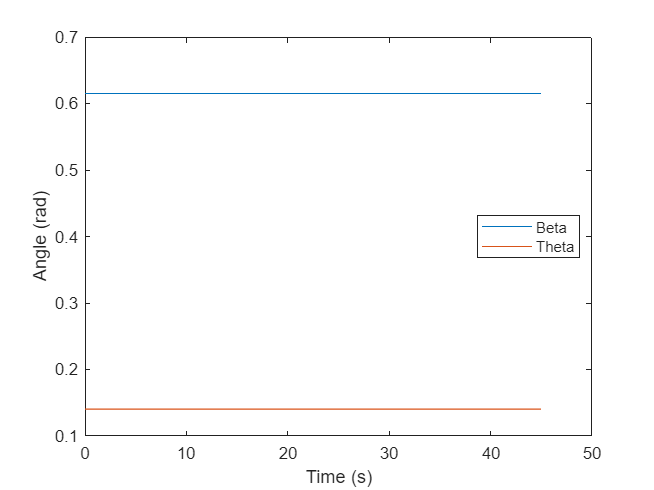


figure
plot(out_axypro.tout, beta, out_axypro.tout, theta)
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Beta", "Theta", "Location", "best")

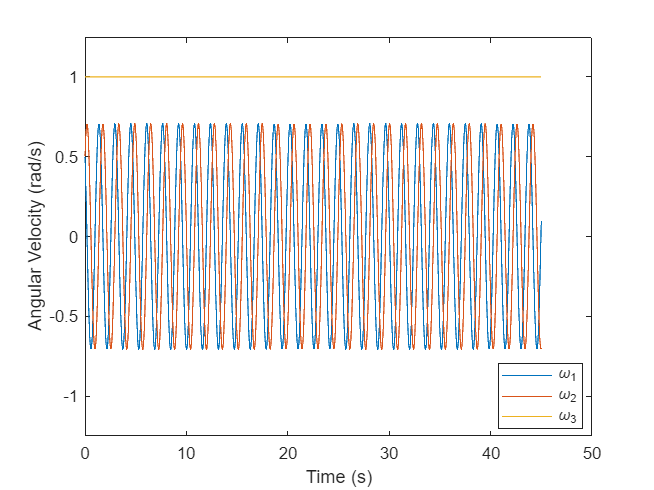


figure
plot(out_axypro.tout, out_axypro.omega(:,1), out_axypro.tout, out_axypro.omega(:,2), out_axypro.tout, out_axypro.omega(:,3))
ylim([-1.25, 1.25])
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
legend("\omega_1", "\omega_2", "\omega_3", "Location", "best")

#### Axisymmetric Oblate Case

I_t = 10;
I_a = 2;
I = [I_t 0 0; 0 I_t 0; 0 0 I_a];
w_0 = [0.05;0.05;1];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;0;0];

out_axyob = runModel(I, g, w_0, e, b3_hat);

e_axyob = out_axyob.angle_out(abs(out_axyob.tout - 5*pi/2) == min(abs(out_axyob.tout - 5*pi/2)), :);
w_axyob = out_axyob.omega(abs(out_axyob.tout - 5*pi/2) == min(abs(out_axyob.tout - 5*pi/2)), :)

w_axyob =     0.0498    0.0502    1.0000


w_inertial_axyob = out_axyob.omega_inertial(abs(out_axyob.tout - 5*pi/2) == min(abs(out_axyob.tout - 5*pi/2)), :);
h_axyob = out_axyob.ang_mom(abs(out_axyob.tout - 5*pi/2) == min(abs(out_axyob.tout - 5*pi/2)), :)

h_axyob =     0.4984    0.5016    2.0000


h_inertial_axyob = out_axyob.ang_mom_inertial(abs(out_axyob.tout - 5*pi/2) == min(abs(out_axyob.tout - 5*pi/2)), :);

beta = acos(out_axyob.omega(:,3)./vecnorm(out_axyob.omega, 2, 2));
theta = acos(out_axyob.ang_mom(:,3)./vecnorm(out_axyob.ang_mom, 2, 2));
beta(1)

ans = 0.0706

theta(1)

ans = 0.3398

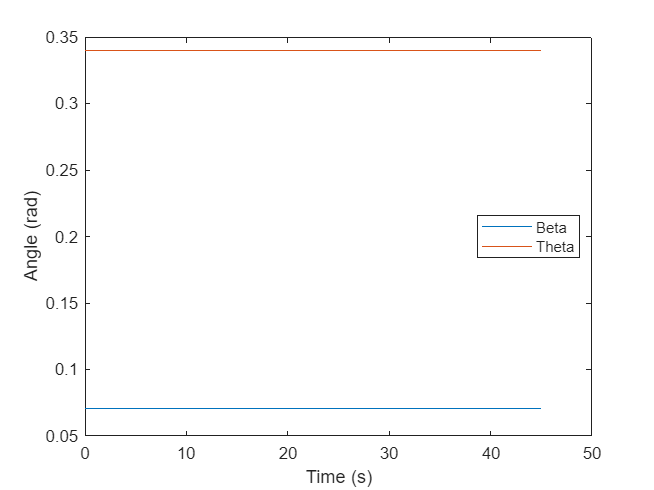


figure
plot(out_axyob.tout, beta, out_axyob.tout, theta)
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Beta", "Theta", "Location", "best")

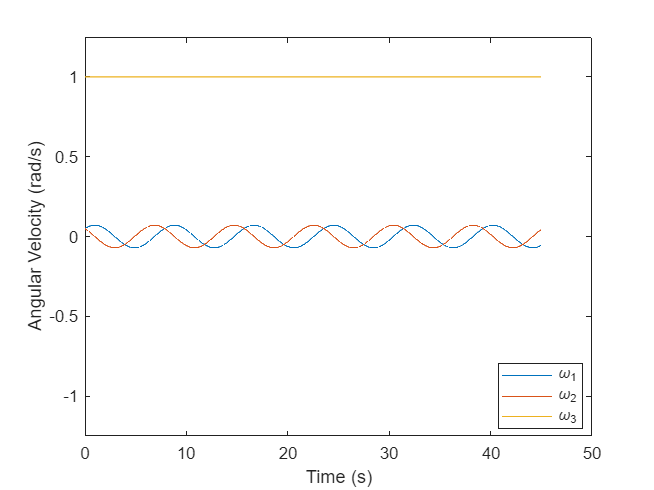


figure
plot(out_axyob.tout, out_axyob.omega(:,1), out_axyob.tout, out_axyob.omega(:,2), out_axyob.tout, out_axyob.omega(:,3))
ylim([-1.25, 1.25])
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
legend("\omega_1", "\omega_2", "\omega_3", "Location", "best")

#### Trinertial Major Case

I = [21 0 0; 0 14 0; 0 0 7];
w_0 = [5;3;3];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;0;0];

out_trimaj = runModel(I, g, w_0, e, b3_hat);

% figure
% plotPolhode(I, w_0, out_trimaj)

#### Trinertial Minor Case

I = [21 0 0; 0 14 0; 0 0 7];
w_0 = [3;3;10];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;0;0];

out_trimin = runModel(I, g, w_0, e, b3_hat);

% figure
% plotPolhode(I, w_0, out_trimin)

#### Trinertial Intermediate Case

I = [21 0 0; 0 14 0; 0 0 7];
w_0 = [1;10;1];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = [0;0;0];

out_triint = runModel(I, g, w_0, e, b3_hat);

% figure
% plotPolhode(I, w_0, out_triint)

#### General Case

DCM = [sqrt(3)/2 0 -1/2;
    0 1 0;
    1/2 0 sqrt(3)/2];

e = [pi/2;pi/6;-pi/2];
I = DCM*[3 0 0; 0 2 0; 0 0 1]*DCM';
w_0 = [0;0;0];
w_o_inertial = w_0;
h = I*w_0;
h_inertial = h;
g = DCM*[0;0;1];

out_gen = runModel(I, g, w_0, e, b3_hat);

e_gen = [2*pi, 0, 0] + out_gen.angle_out(out_gen.tout == 3, :);
w_gen = out_gen.omega(out_gen.tout == 3, :);
w_inertial_gen = out_gen.omega_inertial(out_gen.tout == 3, :)

w_inertial_gen =     0.0000   -0.0000    3.0000


h_gen = out_gen.ang_mom(out_gen.tout == 3, :);
h_inertial_gen = out_gen.ang_mom_inertial(out_gen.tout == 3, :)

h_inertial_gen =     0.0000   -0.0000    3.0000


## Surrogate Phone Satellite

m = 0.214;
a = 0.14775;
c = 0.07153;
b = 0.00821;

Ip = [m/12*(a^2+b^2) 0 0; 0 m/12*(c^2+b^2) 0; 0 0 m/12*(a^2+c^2)];

### Major Axis

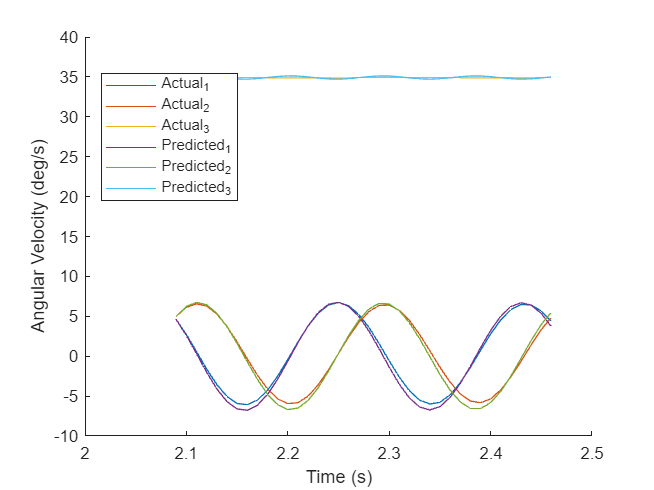

out = load(".\Data\sensorlog_major_axis_2.mat");
w = table2array(timetable2table(out.AngularVelocity, "ConvertRowTimes", false));
e_phone = table2array(timetable2table(out.Orientation, "ConvertRowTimes", false));
t = 0:0.01:(length(w)-1)/100;

e_phone_euler = [];
for i = 1:length(e_phone)
    [phi, theta, psi] = xyz_to_zxz(-e_phone(i,2), e_phone(i,3), -e_phone(i,1));
    e_phone_euler = [e_phone_euler; phi, theta, psi];
end

energy_actual = [];
energy_theoretical = [];

for i = 1:length(w)
    energy = 0.5*(w(i,:)*Ip*w(i,:)');
    energy_actual = [energy_actual; energy];
end

t_0 = 2.09;
t_f = 2.46;

out_majaxis = runModel(Ip, [0;0;0], w(t == t_0,:)', deg2rad(e_phone_euler(t == t_0,:)'), [0;0;1]);

model_t = out_majaxis.tout + t_0;
omega = out_majaxis.omega;
angle = rad2deg([out_majaxis.angle_out(:,1), -out_majaxis.angle_out(:,2), -out_majaxis.angle_out(:,3)]);

for i = 1:length(omega)
    energy = 0.5*(omega(i,:)*Ip*omega(i,:)');
    energy_theoretical = [energy_theoretical; energy];
end

figure
hold on
plot(t((t >= t_0 & t <= t_f)), w((t >= t_0 & t <= t_f),:))
plot(model_t((model_t >= t_0 & model_t <= t_f)), omega((model_t >= t_0 & model_t <= t_f),:))
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")
legend("Actual_1", "Actual_2", "Actual_3", "Predicted_1", "Predicted_2", "Predicted_3", "Location", "best")
hold off

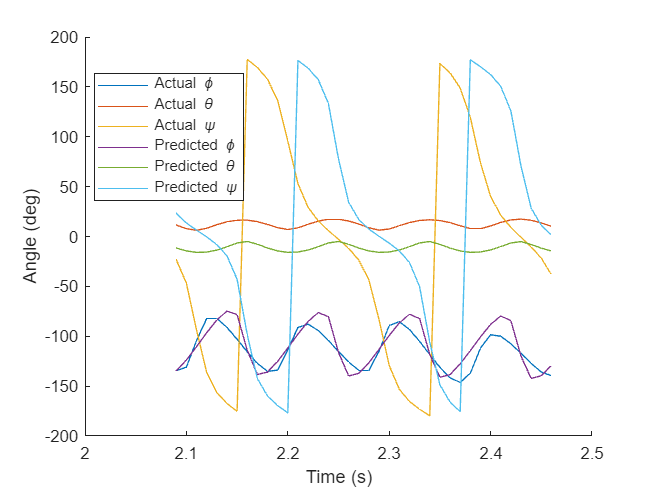


figure
hold on
plot(t((t >= t_0 & t <= t_f)), e_phone_euler((t >= t_0 & t <= t_f),:))
plot(model_t((model_t >= t_0 & model_t <= t_f)), angle((model_t >= t_0 & model_t <= t_f),:))
xlabel("Time (s)")
ylabel("Angle (deg)")
legend("Actual \phi", "Actual \theta", "Actual \psi", "Predicted \phi", "Predicted \theta", "Predicted \psi", "Location", "best")
hold off

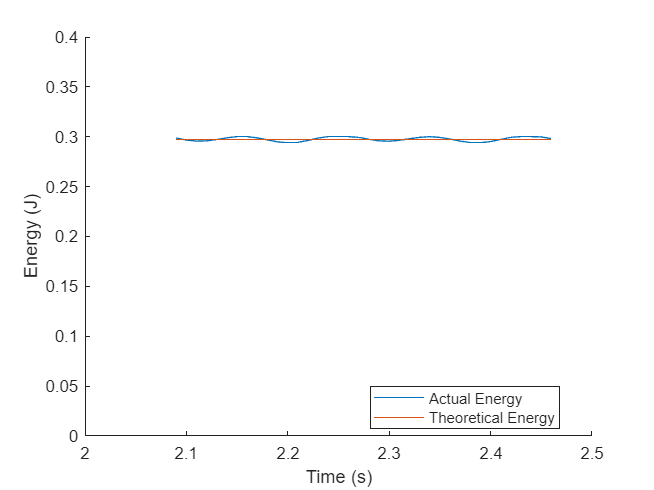


figure
hold on
plot(t((t >= t_0 & t <= t_f)), energy_actual(t >= t_0 & t <= t_f))
plot(t((t >= t_0 & t <= t_f)), energy_theoretical(t >= t_0 & t <= t_f))
xlabel("Time (s)")
ylabel("Energy (J)")
legend("Actual Energy", "Theoretical Energy", "Location", "best")
ylim([0, 0.4])
hold off

### Minor Axis

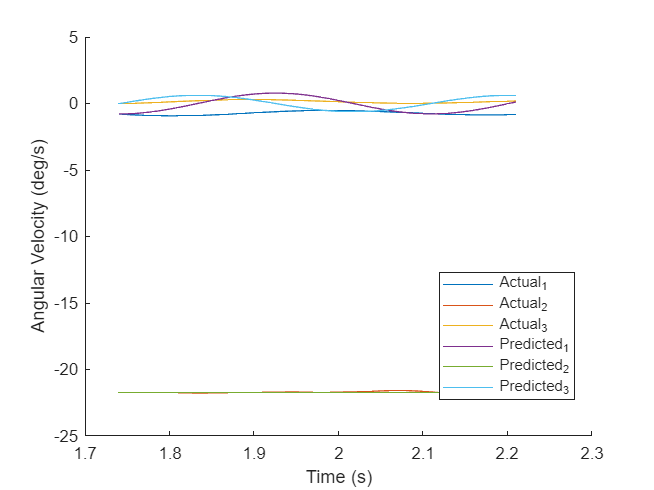

out = load(".\Data\sensorlog_minor_axis_2.mat");
w = table2array(timetable2table(out.AngularVelocity, "ConvertRowTimes", false));
e_phone = table2array(timetable2table(out.Orientation, "ConvertRowTimes", false));
t = 0:0.01:(length(w)-1)/100;

e_phone_euler = [];
for i = 1:length(e_phone)
    [phi, theta, psi] = xyz_to_zxz(-e_phone(i,2), e_phone(i,3), -e_phone(i,1));
    e_phone_euler = [e_phone_euler; phi, theta, psi];
end

energy_actual = [];
energy_theoretical = [];

for i = 1:length(w)
    energy = 0.5*(w(i,:)*Ip*w(i,:)');
    energy_actual = [energy_actual; energy];
end

t_0 = 1.74;
t_f = 2.21;

out_minaxis = runModel(Ip, [0;0;0], w(t == t_0,:)', deg2rad(e_phone_euler(t == t_0,:)'), [0;0;1]);

model_t = out_minaxis.tout + t_0;
omega = out_minaxis.omega;
angle = rad2deg([out_minaxis.angle_out(:,3), out_minaxis.angle_out(:,2), out_minaxis.angle_out(:,1)]);

for i = 1:length(omega)
    energy = 0.5*(omega(i,:)*Ip*omega(i,:)');
    energy_theoretical = [energy_theoretical; energy];
end

figure
hold on
plot(t((t >= t_0 & t <= t_f)), w((t >= t_0 & t <= t_f),:))
plot(model_t((model_t >= t_0 & model_t <= t_f)), omega((model_t >= t_0 & model_t <= t_f),:))
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")
legend("Actual_1", "Actual_2", "Actual_3", "Predicted_1", "Predicted_2", "Predicted_3", "Location", "best")
hold off

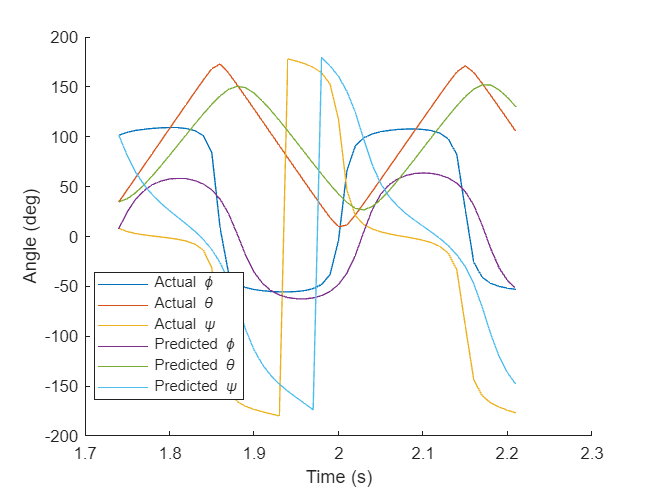


figure
hold on
plot(t((t >= t_0 & t <= t_f)), e_phone_euler((t >= t_0 & t <= t_f),:))
plot(model_t((model_t >= t_0 & model_t <= t_f)), angle((model_t >= t_0 & model_t <= t_f),:))
xlabel("Time (s)")
ylabel("Angle (deg)")
legend("Actual \phi", "Actual \theta", "Actual \psi", "Predicted \phi", "Predicted \theta", "Predicted \psi", "Location", "best")
hold off

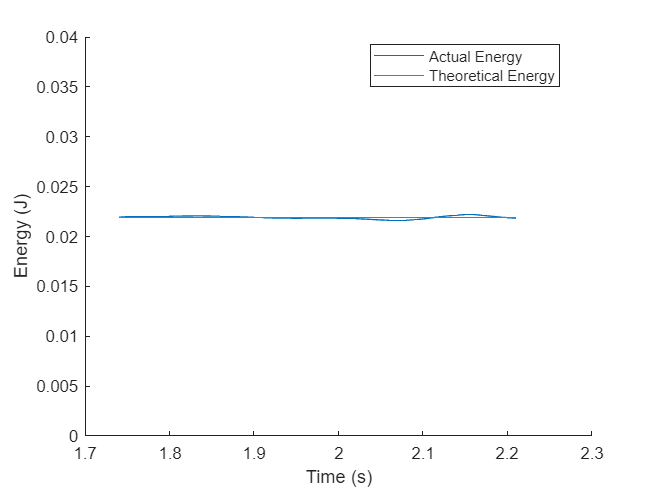


figure
hold on
plot(t((t >= t_0 & t <= t_f)), energy_actual(t >= t_0 & t <= t_f))
plot(t((t >= t_0 & t <= t_f)), energy_theoretical(t >= t_0 & t <= t_f))
xlabel("Time (s)")
ylabel("Energy (J)")
legend("Actual Energy", "Theoretical Energy", "Location", "best")
ylim([0, 0.04])
hold off

### Intermediate Axis

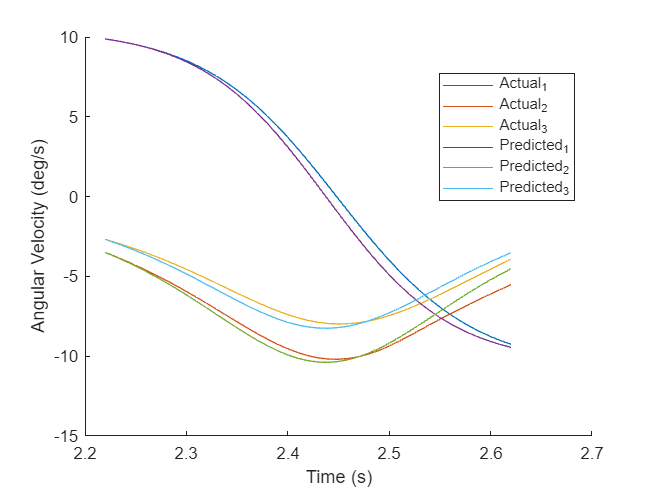

out = load(".\Data\sensorlog_intermediate.mat");
w = table2array(timetable2table(out.AngularVelocity, "ConvertRowTimes", false));
e_phone = table2array(timetable2table(out.Orientation, "ConvertRowTimes", false));
t = 0:0.01:(length(w)-1)/100;

e_phone_euler = [];
for i = 1:length(e_phone)
    [phi, theta, psi] = xyz_to_zxz(-e_phone(i,2), e_phone(i,3), -e_phone(i,1));
    e_phone_euler = [e_phone_euler; phi, theta, psi];
end

energy_actual = [];
energy_theoretical = [];

for i = 1:length(w)
    energy = 0.5*(w(i,:)*Ip*w(i,:)');
    energy_actual = [energy_actual; energy];
end

t_0 = 2.22;
t_f = 2.63;

out_intaxis_pure = runModel(Ip, [0;0;0], w(t == t_0,:)', deg2rad(e_phone_euler(t == t_0,:)'), [0;0;1]);

model_t = out_intaxis_pure.tout + t_0;
omega = out_intaxis_pure.omega;
angle = rad2deg([out_intaxis_pure.angle_out(:,1), out_intaxis_pure.angle_out(:,2), out_intaxis_pure.angle_out(:,3)]);

for i = 1:length(omega)
    energy = 0.5*(omega(i,:)*Ip*omega(i,:)');
    energy_theoretical = [energy_theoretical; energy];
end

figure
hold on
plot(t((t >= t_0 & t <= t_f)), w((t >= t_0 & t <= t_f),:))
plot(model_t((model_t >= t_0 & model_t <= t_f)), omega((model_t >= t_0 & model_t <= t_f),:))
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")
legend("Actual_1", "Actual_2", "Actual_3", "Predicted_1", "Predicted_2", "Predicted_3", "Location", "best")
hold off

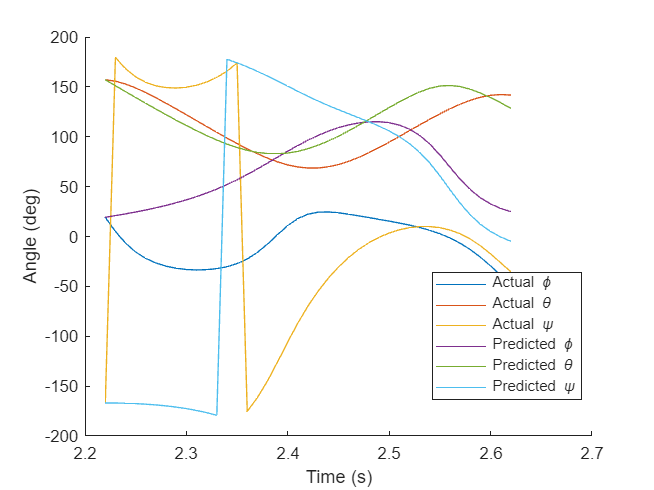


figure
hold on
plot(t((t >= t_0 & t <= t_f)), e_phone_euler((t >= t_0 & t <= t_f),:))
plot(model_t((model_t >= t_0 & model_t <= t_f)), angle((model_t >= t_0 & model_t <= t_f),:))
xlabel("Time (s)")
ylabel("Angle (deg)")
legend("Actual \phi", "Actual \theta", "Actual \psi", "Predicted \phi", "Predicted \theta", "Predicted \psi", "Location", "best")
hold off

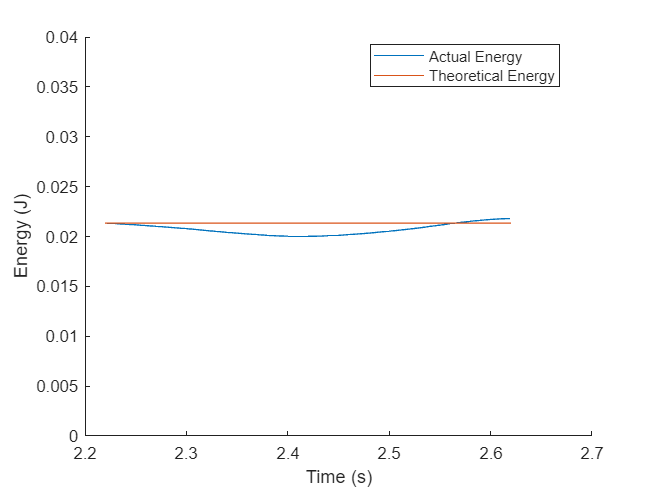


figure
hold on
plot(t((t >= t_0 & t <= t_f)), energy_actual(t >= t_0 & t <= t_f))
plot(t((t >= t_0 & t <= t_f)), energy_theoretical(t >= t_0 & t <= t_f))
xlabel("Time (s)")
ylabel("Energy (J)")
legend("Actual Energy", "Theoretical Energy", "Location", "best")
ylim([0, 0.04])
hold off

## FalconSAT-Ex

I_b = [15.6 -0.2 -0.2;
    -0.2 14.3 -0.2;
    -0.2 -0.2 7.9];
b3_hat = [0;0;1];

### Case 1

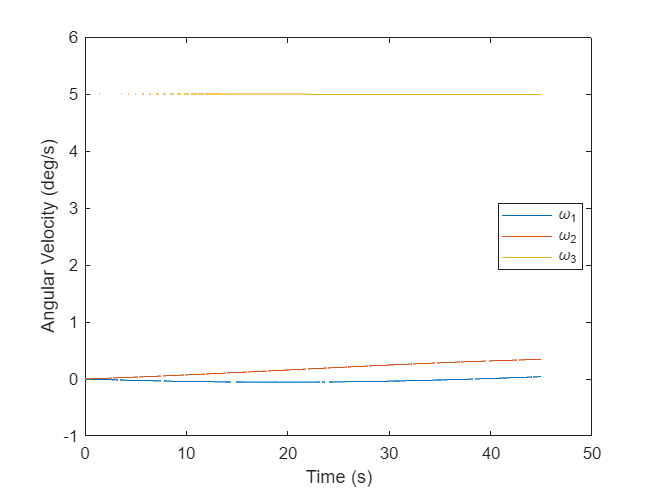

w_0 = deg2rad([0;0;5]);
e = deg2rad([0 0.57 0]);
g = [0;0;0];

out_case1 = runModel(I_b, g, w_0, e, b3_hat);

figure
plot(out_case1.tout, rad2deg(out_case1.omega))
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")
legend("\omega_1", "\omega_2", "\omega_3", "Location", "best")

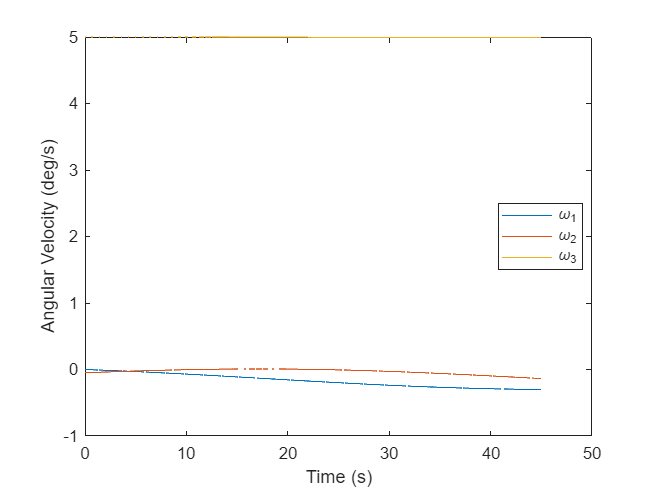


% figure
% animateVector(rad2deg(out_case1.omega), out_case1.tout)

figure
plot(out_case1.tout, rad2deg(out_case1.omega_inertial))
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")
legend("\omega_1", "\omega_2", "\omega_3", "Location", "best")

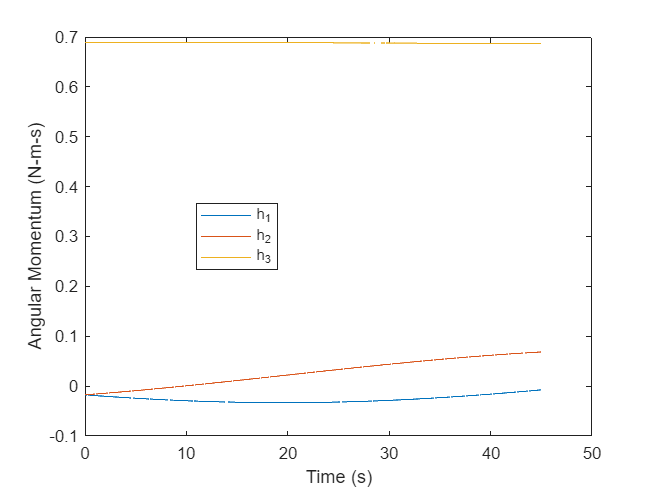


% figure
% animateVector(rad2deg(out_case1.omega_inertial), out_case1.tout)

figure
plot(out_case1.tout, out_case1.ang_mom)
xlabel("Time (s)")
ylabel("Angular Momentum (N-m-s)")
legend("h_1", "h_2", "h_3", "Location", "best")

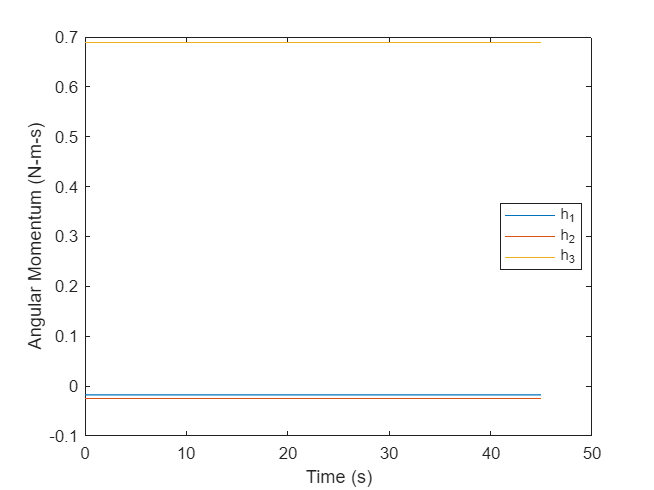


% figure
% animateVector(out_case1.ang_mom, out_case1.tout)

figure
plot(out_case1.tout, out_case1.ang_mom_inertial)
xlabel("Time (s)")
ylabel("Angular Momentum (N-m-s)")
legend("h_1", "h_2", "h_3", "Location", "best")

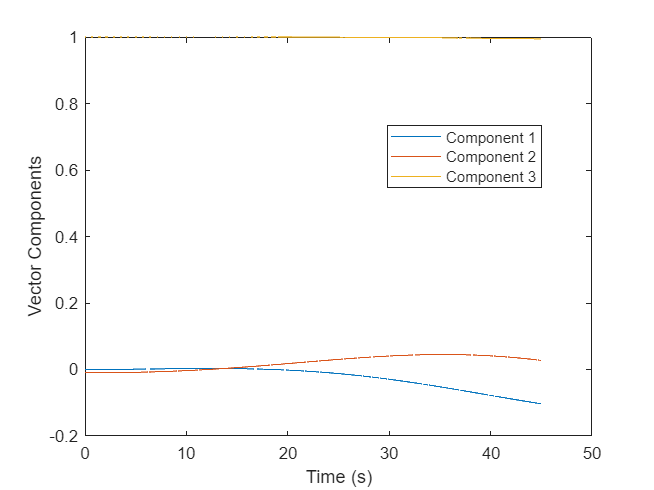


% figure
% animateVector(out_case1.ang_mom_inertial, out_case1.tout)

figure
plot(out_case1.tout, out_case1.b3hat_inertial)
xlabel("Time (s)")
ylabel("Vector Components")
legend("Component 1", "Component 2", "Component 3", "Location", "best")

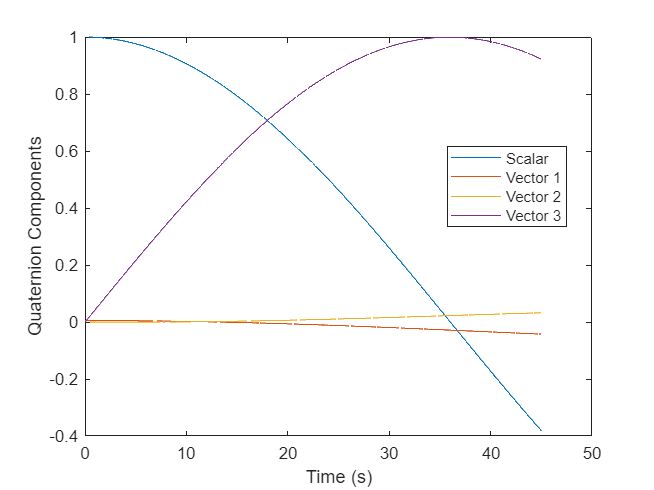


% figure
% animateVector(out_case1.b3hat_inertial, out_case1.tout)

figure
plot(out_case1.tout, out_case1.q)
xlabel("Time (s)")
ylabel("Quaternion Components")
legend("Scalar", "Vector 1", "Vector 2", "Vector 3", "Location", "best")

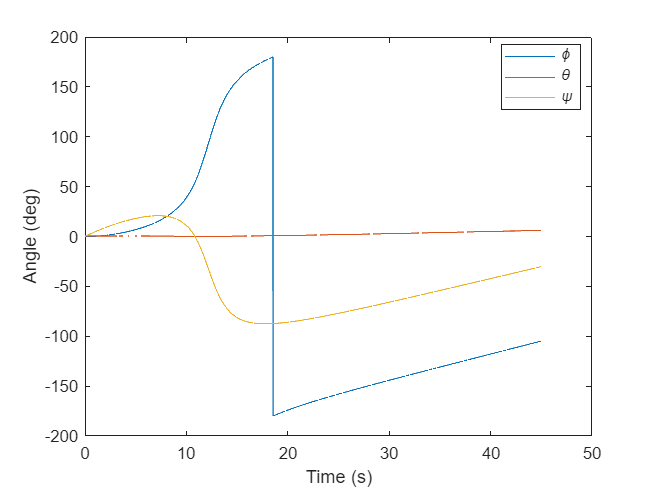


figure
plot(out_case1.tout, rad2deg(out_case1.angle_out))
xlabel("Time (s)")
ylabel("Angle (deg)")
legend("\phi", "\theta", "\psi", "Location", "best")

### Case 2

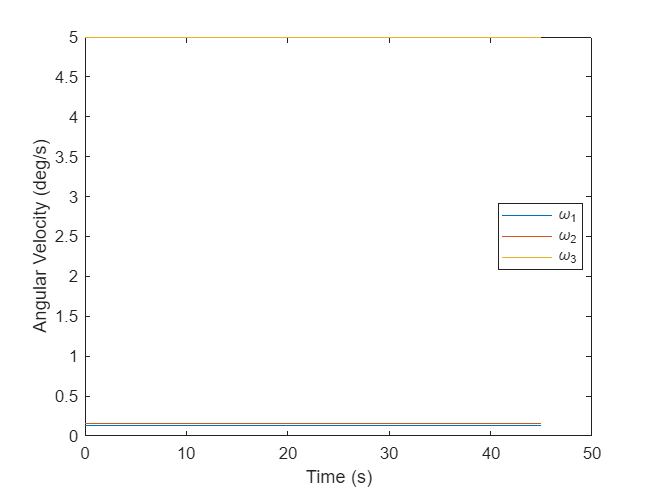

w_0 = deg2rad([0.1337;0.16;4.9957]);
e = deg2rad([0 0.57 0]);
g = [0;0;0];

out_case2 = runModel(I_b, g, w_0, e, b3_hat);

figure
plot(out_case2.tout, rad2deg(out_case2.omega))
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")
legend("\omega_1", "\omega_2", "\omega_3", "Location", "best")

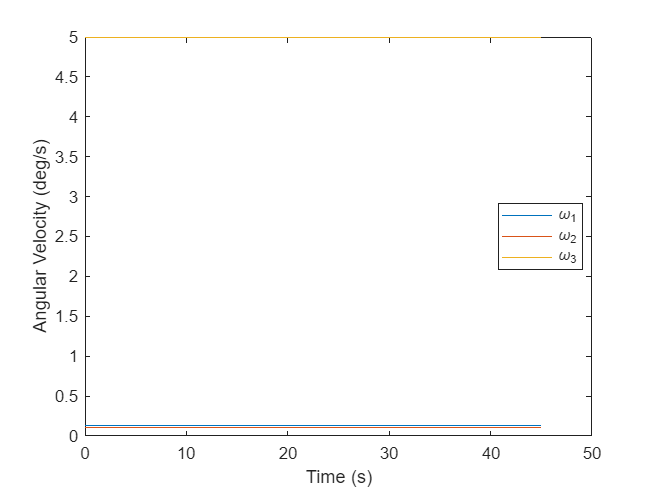


% figure
% animateVector(rad2deg(out_case2.omega), out_case2.tout)

figure
plot(out_case2.tout, rad2deg(out_case2.omega_inertial))
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")
legend("\omega_1", "\omega_2", "\omega_3", "Location", "best")

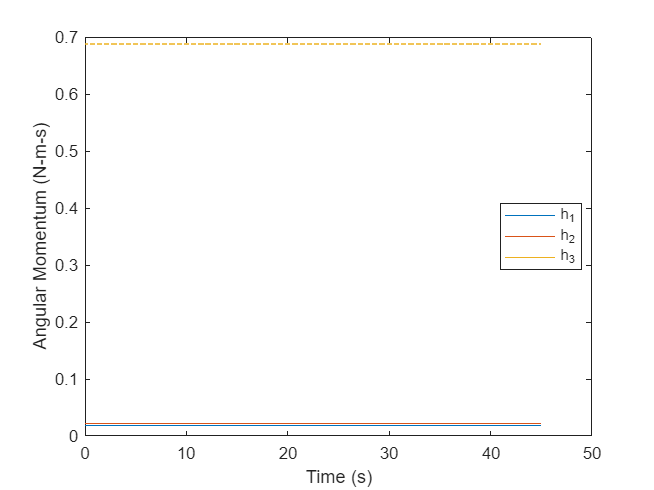

% figure
% animateVector(rad2deg(out_case2.omega_inertial), out_case2.tout)

figure
plot(out_case2.tout, out_case2.ang_mom)
xlabel("Time (s)")
ylabel("Angular Momentum (N-m-s)")
legend("h_1", "h_2", "h_3", "Location", "best")

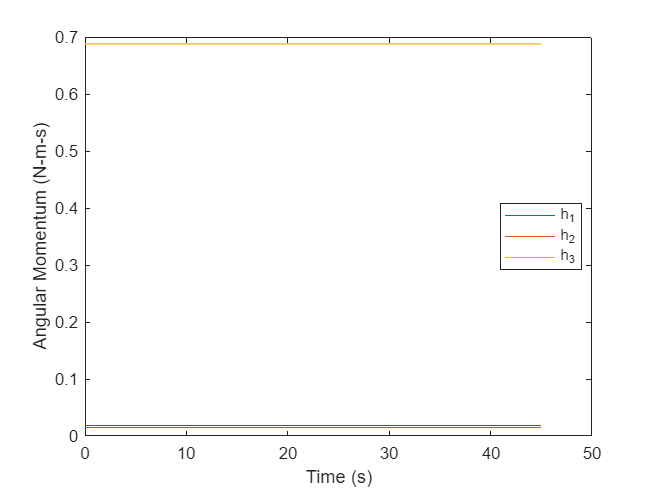


% figure
% animateVector(out_case2.ang_mom, out_case2.tout)

figure
plot(out_case2.tout, out_case2.ang_mom_inertial)
xlabel("Time (s)")
ylabel("Angular Momentum (N-m-s)")
legend("h_1", "h_2", "h_3", "Location", "best")

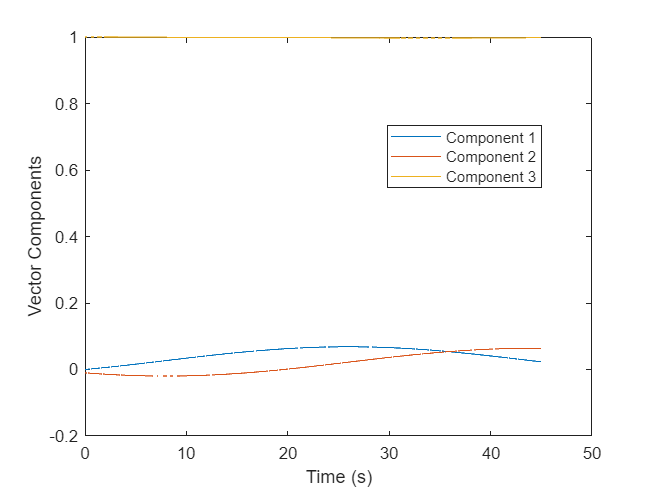


% figure
% animateVector(out_case2.ang_mom_inertial, out_case2.tout)

figure
plot(out_case2.tout, out_case2.b3hat_inertial)
xlabel("Time (s)")
ylabel("Vector Components")
legend("Component 1", "Component 2", "Component 3", "Location", "best")

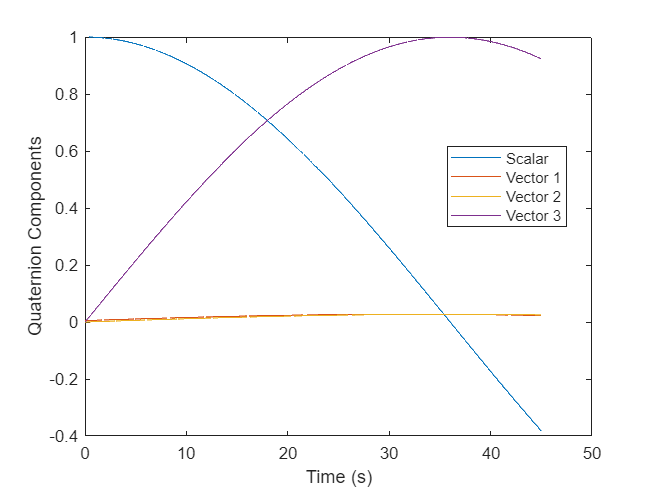


% figure
% animateVector(out_case2.b3hat_inertial, out_case2.tout)

figure
plot(out_case2.tout, out_case2.q)
xlabel("Time (s)")
ylabel("Quaternion Components")
legend("Scalar", "Vector 1", "Vector 2", "Vector 3", "Location", "best")

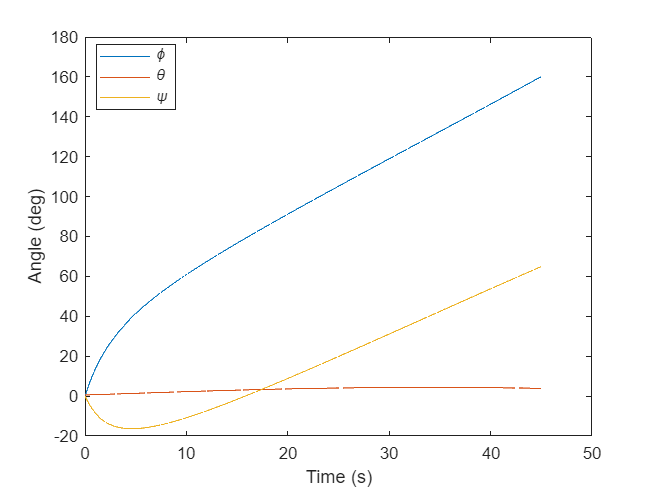


figure
plot(out_case2.tout, rad2deg(out_case2.angle_out))
xlabel("Time (s)")
ylabel("Angle (deg)")
legend("\phi", "\theta", "\psi", "Location", "best")

### Case 3

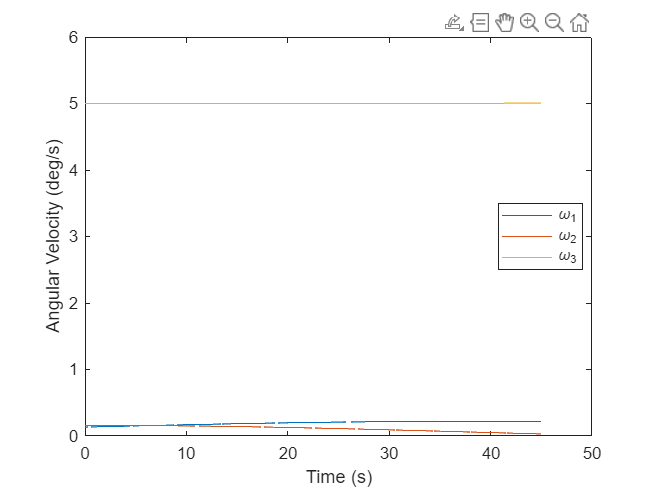

w_0 = deg2rad([0.1337;0.16;4.9957]);
e = deg2rad([0 0.57 0]);
g = [0.001;0;0];

out_case3 = runModel(I_b, g, w_0, e, b3_hat);

figure
plot(out_case3.tout, rad2deg(out_case3.omega))
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")
legend("\omega_1", "\omega_2", "\omega_3", "Location", "best")

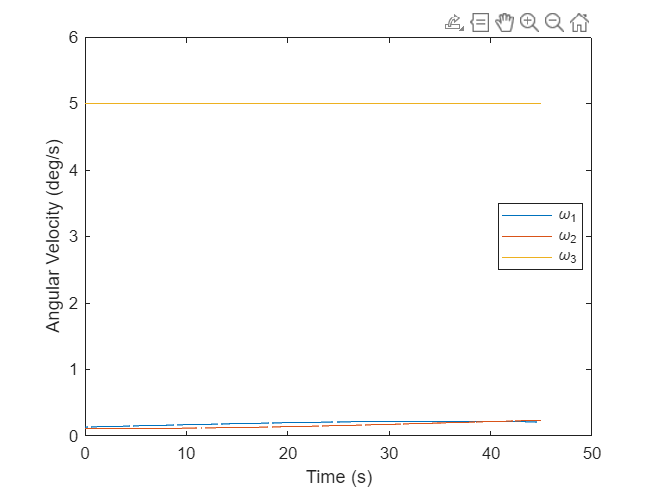


% figure
% animateVector(rad2deg(out_case3.omega), out_case3.tout)

figure
plot(out_case3.tout, rad2deg(out_case3.omega_inertial))
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")
legend("\omega_1", "\omega_2", "\omega_3", "Location", "best")

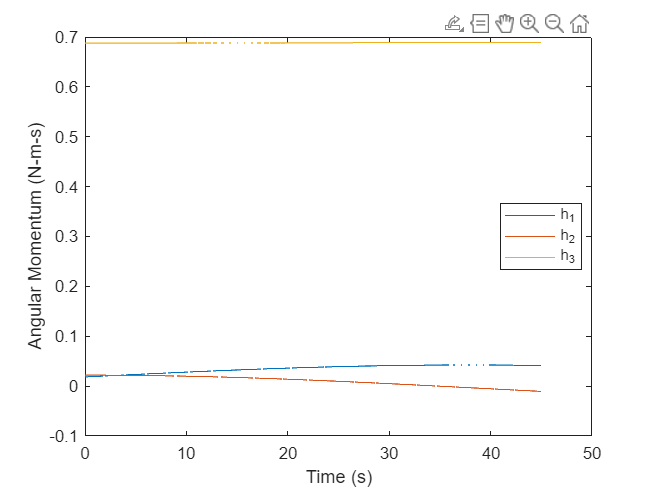


% figure
% animateVector(rad2deg(out_case3.omega_inertial), out_case3.tout)

figure
plot(out_case3.tout, out_case3.ang_mom)
xlabel("Time (s)")
ylabel("Angular Momentum (N-m-s)")
legend("h_1", "h_2", "h_3", "Location", "best")

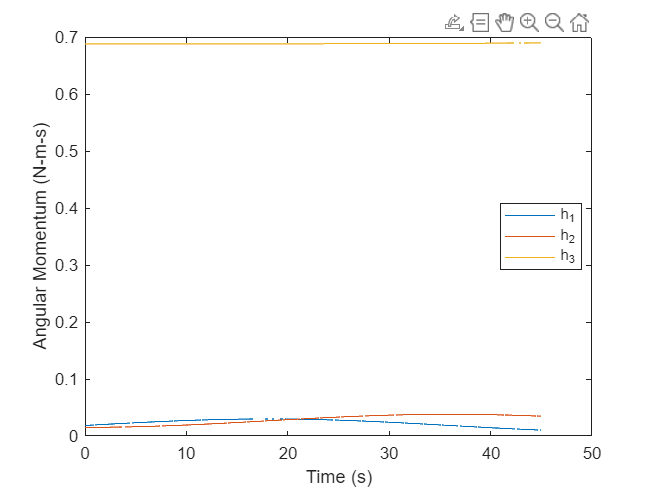


% figure
% animateVector(out_case3.ang_mom, out_case3.tout)

figure
plot(out_case3.tout, out_case3.ang_mom_inertial)
xlabel("Time (s)")
ylabel("Angular Momentum (N-m-s)")
legend("h_1", "h_2", "h_3", "Location", "best")

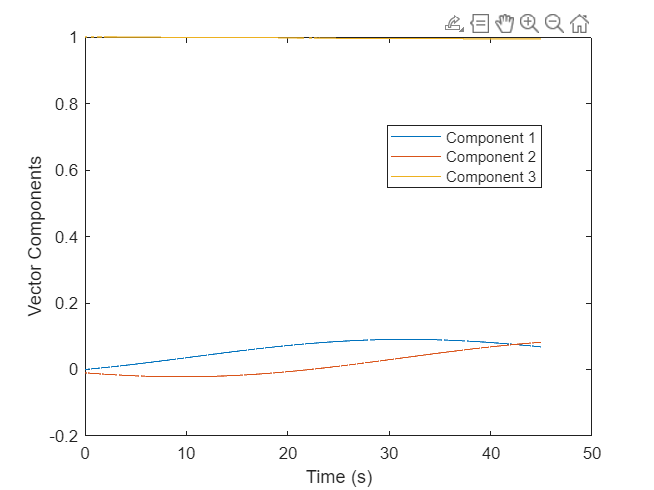


% figure
% animateVector(out_case3.ang_mom_inertial, out_case3.tout)

figure
plot(out_case3.tout, out_case3.b3hat_inertial)
xlabel("Time (s)")
ylabel("Vector Components")
legend("Component 1", "Component 2", "Component 3", "Location", "best")

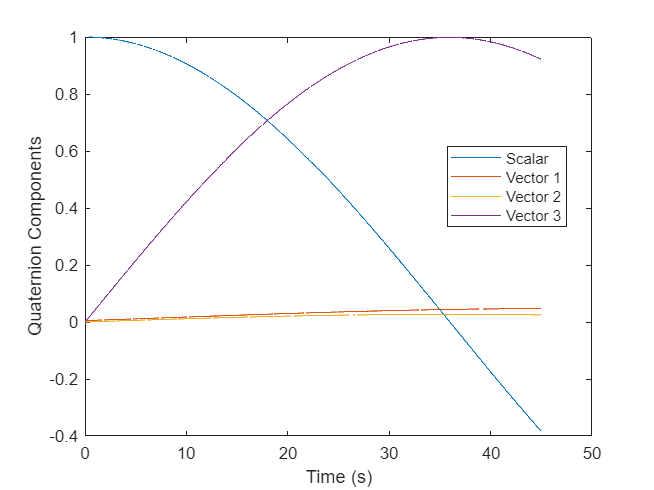


% figure
% animateVector(out_case3.b3hat_inertial, out_case3.tout)

figure
plot(out_case3.tout, out_case3.q)
xlabel("Time (s)")
ylabel("Quaternion Components")
legend("Scalar", "Vector 1", "Vector 2", "Vector 3", "Location", "best")

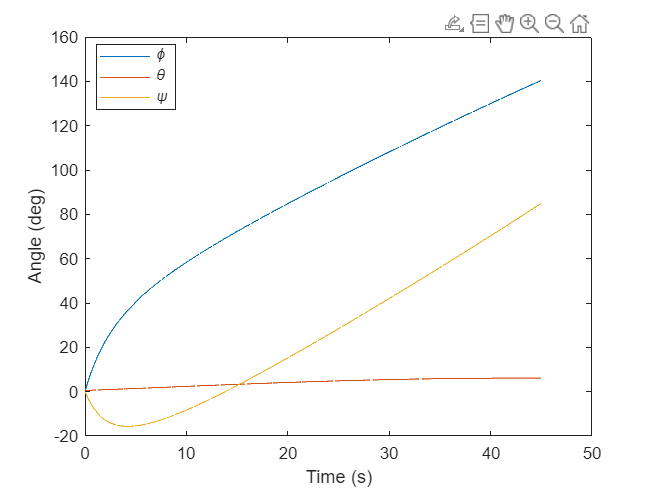


figure
plot(out_case3.tout, rad2deg(out_case3.angle_out))
xlabel("Time (s)")
ylabel("Angle (deg)")
legend("\phi", "\theta", "\psi", "Location", "best")